# Acoustic Tunnel Geometry Tests

create the geometry for the acoustic ray tracing/ESM and run some simple tests for the source ray directions and ray-geometry/ESM interactions as well as interpolation methods.

#### Set up the array microphone and canvas positions

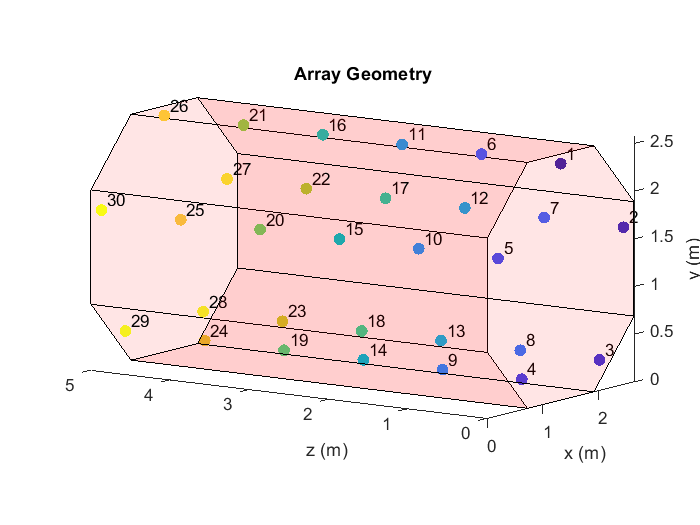

%create some number of points, to create a set of patch objects that will
%define the ESM for, this is the geometry of the array
%take the bottom left of the array as 0,0,0 woth the x axis pointing to the
%right, y axis pointing up and z azis pointing forward

%set the number of array microphones
numArrayMics = 30;
arrayMicNums = [1:1:30]';

%distance between each ring (m)
ringDists = 1;

%distance between each microphone (pentagon)
pentDist = 1.4;

%hexagon vertical distance
hexVertDist = 1.2;

%hexagon diagonal distance
hexDiagDist = 1;

%note that the pentagon is centered at the top, so we need to construct the
%correct geometry to place all the microphones
%the mic locations for mics around the ring, 1-5
mic1Pos = [1.32 2.48];
mic2Pos = [2.45 1.65];
mic3Pos = [2.02 0.32];
mic4Pos = [0.62 0.32];
mic5Pos = [0.19 1.65];

%combine into the total mic positions for each ring
totalMicPosXYEachRing = [mic1Pos;mic2Pos;mic3Pos;mic4Pos;mic5Pos];

%z positions
micPosZ = [0*ones([5,1]);1*ones([5,1]);2*ones([5,1]);3*ones([5,1]);4*ones([5,1]);5*ones([5,1])];

%combine into the total microphone positions in the array
micPositions = [totalMicPosXYEachRing;totalMicPosXYEachRing;totalMicPosXYEachRing;totalMicPosXYEachRing;totalMicPosXYEachRing;totalMicPosXYEachRing];
micPositions = [micPositions,micPosZ];

%do the same thing for the canvas positions, in this case it starts with
%bottom left
canvas1Pos = [0.72 0];
canvas2Pos = [0 0.69];
canvas3Pos = [0 1.89];
canvas4Pos = [0.72 2.58];
canvas5Pos = [1.92 2.58];
canvas6Pos = [2.64 1.89];
canvas7Pos = [2.64 0.69];
canvas8Pos = [1.92 0];

%z positions
canvasPosZ = [0*ones([8,1]);1*ones([8,1]);2*ones([8,1]);3*ones([8,1]);4*ones([8,1]);5*ones([8,1])];

%combine into the total canvas positions for each ring
totalCanvasPosXYEachRing = [canvas1Pos;canvas2Pos;canvas3Pos;canvas4Pos;canvas5Pos;...
    canvas6Pos;canvas7Pos;canvas8Pos];

%create all
canvasPositions = [totalCanvasPosXYEachRing;totalCanvasPosXYEachRing;totalCanvasPosXYEachRing;totalCanvasPosXYEachRing;...
    totalCanvasPosXYEachRing;totalCanvasPosXYEachRing];
canvasPositions = [canvasPositions,canvasPosZ];

%plot all the canvas positions and microphone positions
figure(1)
clf 
hold on
%scatter3(canvasPositions(:,1),canvasPositions(:,2),canvasPositions(:,3),'r*');
scatter3(micPositions(:,1),micPositions(:,2),micPositions(:,3),50,[1:1:size(micPositions,1)],'filled');
axis equal

%create the patch, we need 8 patches, so get the rectangles we need
rectangles = zeros([8,4,3]);
for i = 1:7
    rectangles(i,:,:) = [canvasPositions(i,:);canvasPositions(i+1,:);canvasPositions(8*5 + i+1,:);canvasPositions(8*5 + i,:)];
    patch(rectangles(i,:,1),rectangles(i,:,2),rectangles(i,:,3),[1 0 0],"FaceAlpha",0.1);
end
    rectangles(8,:,:) = [canvasPositions(8,:);canvasPositions(1,:);canvasPositions(8*5 + 1,:);canvasPositions(8*5 + 8,:)];
    patch(rectangles(8,:,1),rectangles(8,:,2),rectangles(8,:,3),[1 0 0],"FaceAlpha",0.1);
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')

%center point
centerPoint = mean([canvasPositions(1:8,:);canvasPositions(end-7:end,:)]);
%scatter3(centerPoint(1),centerPoint(2),centerPoint(3),'k','filled');

%create a set of normal vectors that point into the center of the array,
%one for each rectangle

%create some vectors for each rectangle
rectangleCenters = squeeze(mean(rectangles,2)); 
arrayWallNorms = [];
for i = 1:7
    vec1 = canvasPositions(i + 1,:) - canvasPositions(i,:);
    vec2 = canvasPositions(40 + i,:) - canvasPositions(i,:);
    crossVec = -1*cross(vec1,vec2)/norm(cross(vec1,vec2));
    arrayWallNorms = [arrayWallNorms;crossVec];
    %quiver3(rectangleCenters(i,1),rectangleCenters(i,2),rectangleCenters(i,3),crossVec(1),crossVec(2),crossVec(3),'LineWidth',3);
end

%scatter3(rectangleCenters(:,1),rectangleCenters(:,2),rectangleCenters(:,3));
text(micPositions(:,1) + 0.1,micPositions(:,2) + 0.1,micPositions(:,3),string([1:1:30]));
% text(centerPoint(1),centerPoint(2),centerPoint(3) - 5,'Front')
% text(centerPoint(1),centerPoint(2),centerPoint(3) + 5,'Rear')
title('Array Geometry')
camorbit(55,-10,'camera')
hold off
axis equal

#### Create a set of points inside the array

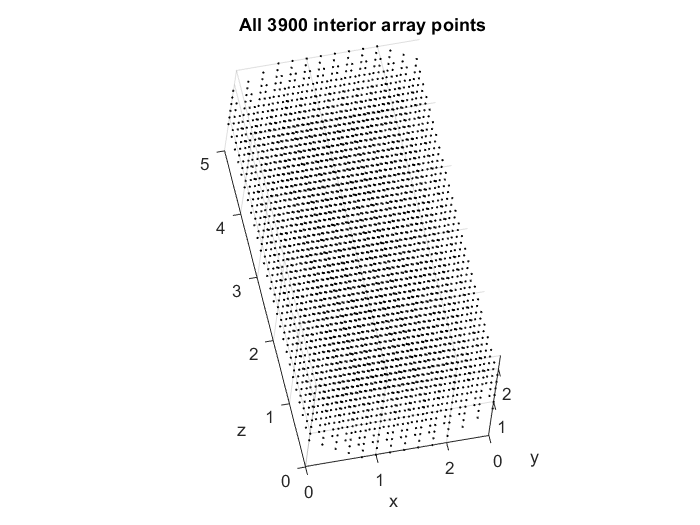

%create a set of points inside the array, such that we know which points to
%evaluate for
minArrayX = min(canvasPositions(:,1));
maxArrayX = max(canvasPositions(:,1));
minArrayY = min(canvasPositions(:,2));
maxArrayY = max(canvasPositions(:,2));
minArrayZ = min(canvasPositions(:,3));
maxArrayZ = max(canvasPositions(:,3));

%create a set of evenly spaced points 
pointSpacing = 0.2;
[X,Y,Z] = meshgrid(minArrayX:pointSpacing:maxArrayX,minArrayY:pointSpacing:maxArrayY,minArrayZ:pointSpacing:maxArrayZ);

%create a set of unordered array points for which to set as inside the
%walls or not
unorderedArrayPoints = -1*ones([size(X,1)*size(Y,1)*size(Z,1) 3]);

%for the first ring (z = 0), determine if the points are inside or outside
%the hexagon, if outside set them as negative
inPoints = double(inpolygon(X(:,:,1),Y(:,:,1),canvasPositions(1:8,1),canvasPositions(1:8,2)));
inPoints(inPoints == 0 ) = -nan;

%now multiply this by all the z slices and set anything negative to -1
%(ignore it basically)
X = X.*inPoints;
Y = Y.*inPoints;
Z = Z.*inPoints;

%get the array interior points
interiorPoints = [X(:), Y(:), Z(:)];
interiorArrayPoints = rmmissing(interiorPoints);

%scatter these to see the inside of the array
figure(2)
clf
scatter3(interiorArrayPoints(:,1),interiorArrayPoints(:,2),interiorArrayPoints(:,3),1,'k');
xlabel('x')
ylabel('y')
zlabel('z')
camorbit(45,-5,'camera')
axis equal
title("All " + string(length(interiorArrayPoints)) + " interior array points");

#### Plot the most basic acoustic pattern in the array

first use a scatter plot, then some contours

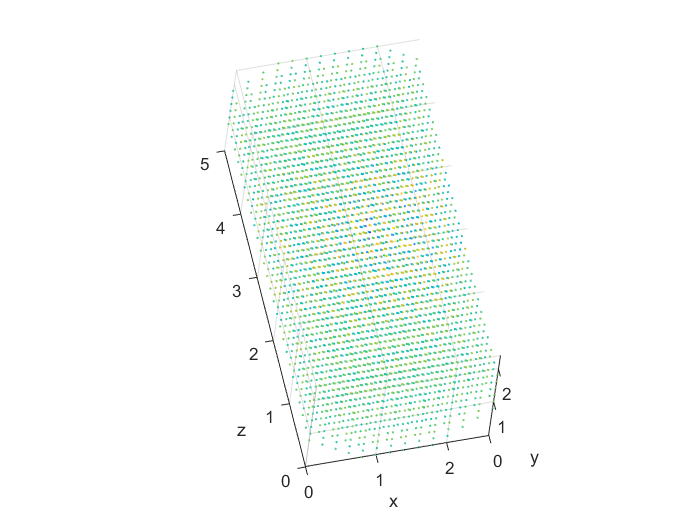

%random inside point as the 'source'
sourcePoint = centerPoint + [0.2 0.2 0.2];

%create a randomized direction vector
randDirecVec = rand([1,3]);
randDirecVec = randDirecVec/norm(randDirecVec);

%just plot the proximity of a point to those in the array
proximityPoints = vecnorm(sourcePoint - interiorArrayPoints,2,2);

%take the sine of it to crate some waves??
proximityWaves = (1./proximityPoints).*sin(20*proximityPoints);

%set the size and color based on the proximity
figure(3)
clf
scatter3(interiorArrayPoints(:,1),interiorArrayPoints(:,2),interiorArrayPoints(:,3),1,proximityWaves);
xlabel('x')
ylabel('y')
zlabel('z')
camorbit(45,-5,'camera')
axis equal

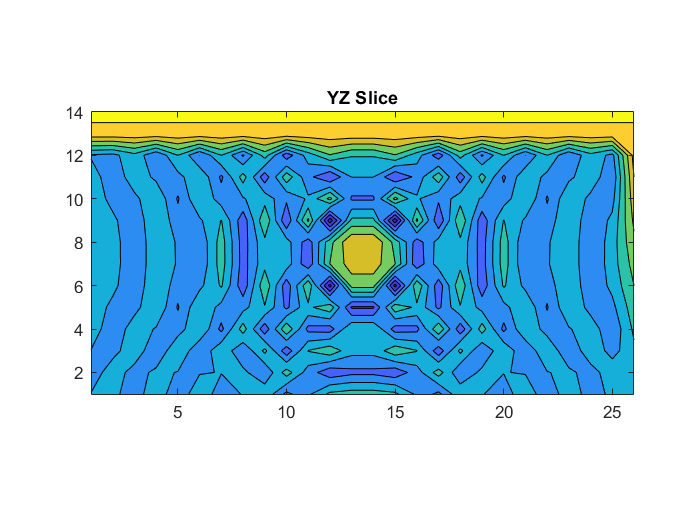

%take some slices, make sure it goes through the midplane, x y and z
%convert the points back to indices
interiorArrayIndices = round(interiorArrayPoints/pointSpacing);
interiorArrayIndices(interiorArrayIndices == 0) = 1;
fullData = X;

%set all the data
for i = 1:size(interiorArrayIndices,1)
    fullData(interiorArrayIndices(i,1),interiorArrayIndices(i,2),interiorArrayIndices(i,3)) = proximityWaves(i);
end

%get a slice
figure(4)
clf
contourf(squeeze(fullData(6,:,:)));
title('YZ Slice')
axis equal

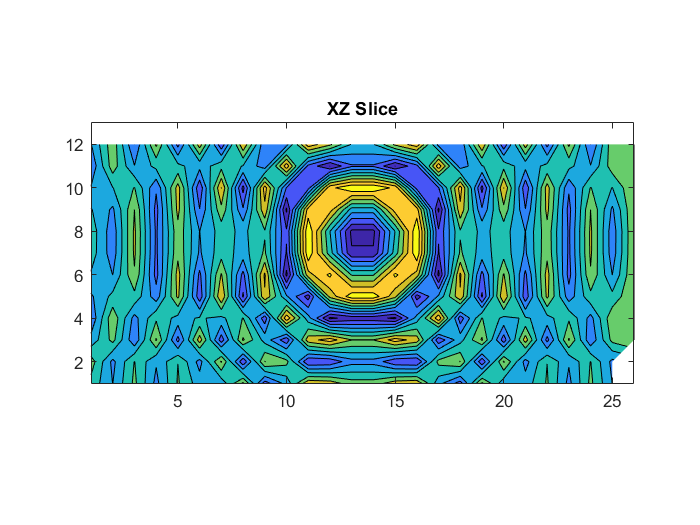


contourf(squeeze(fullData(:,3,:)));
title('XZ Slice')
axis equal

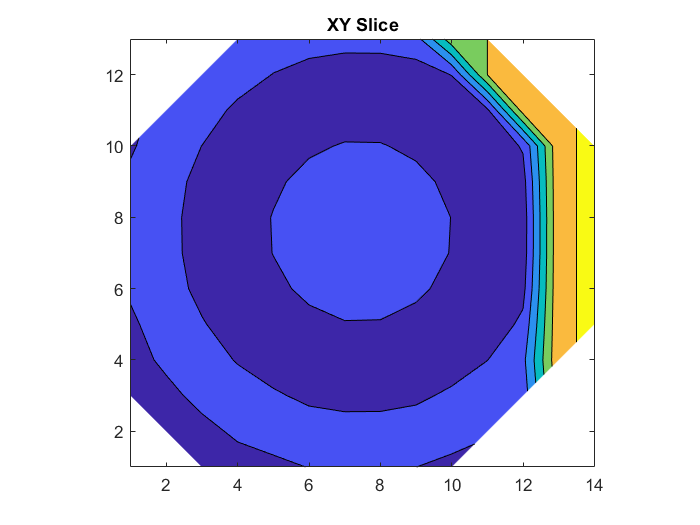

contourf(squeeze(fullData(:,:,2)));
title('XY Slice')
axis equal

%save all the acoustics array data which is needed for the ray tracing
fullArrayDataGeom = fullData;
interiorArrayPointsUnordered = interiorArrayPoints;
arrayFullGeomData = struct("interiorArrayPointsUnordered",interiorArrayPointsUnordered,"fullArrayDataGeom",fullArrayDataGeom,"pointSpacing",pointSpacing,...
    "centerPoint",centerPoint,"arrayWallNorms",arrayWallNorms,"canvasPositions",canvasPositions,"interiorArrayIndices",interiorArrayIndices,"maxArrayX",maxArrayX,...
    "maxArrayY",maxArrayY,"maxArrayZ",maxArrayZ,"micPositions",micPositions,"rectangleCenters",rectangleCenters,"rectangles",rectangles);
save("AcousticTunnelBasicGeometrySparse.mat","arrayFullGeomData");

#### Compute the primary (and even secondary) source reflections

%first we compute the equations of each of the planes, this is easy because
%compute the projected points
reflectedSourcePoints = [];
for i = 1:size(arrayWallNorms,1)
    reflectedPoint = dot(sourcePoint - rectangleCenters(i,:),arrayWallNorms(i,:))*(-2*arrayWallNorms(i,:)) + sourcePoint;
    reflectedSourcePoints = [reflectedSourcePoints; reflectedPoint];
end


%show the projected and reflected points in the tunnel
figure(8)
clf 
hold on

%plot the source
scatter3(sourcePoint(1),sourcePoint(2),sourcePoint(3),'k','filled');

%create plot the direction vector
quiver3(sourcePoint(1),sourcePoint(2),sourcePoint(3),randDirecVec(1),randDirecVec(2),randDirecVec(3),'LineWidth',3);

%plot the array walls
for i = 1:7
    patch(rectangles(i,:,1),rectangles(i,:,2),rectangles(i,:,3),[1 0 0],"FaceAlpha",0.1);
end
patch(rectangles(8,:,1),rectangles(8,:,2),rectangles(8,:,3),[1 0 0],"FaceAlpha",0.1);

%plot the reflected sources
scatter3(reflectedSourcePoints(:,1),reflectedSourcePoints(:,2),reflectedSourcePoints(:,3),'magenta','filled');


%for the vectors, it's a bit easier, we just use a basic formula
reflectedVectors = [];
for i = 1:length(reflectedSourcePoints)
    reflecVec = randDirecVec - 2*dot(randDirecVec,arrayWallNorms(i,:)).*arrayWallNorms(i,:);
    reflectedVectors = [reflectedVectors;reflecVec];
    %plot em'
    quiver3(reflectedSourcePoints(i,1),reflectedSourcePoints(i,2),reflectedSourcePoints(i,3),reflecVec(1),reflecVec(2),reflecVec(3),'LineWidth',3);
 
end
title('Reflection Vectors')
xlabel('x')
ylabel('y')
zlabel('z')
camorbit(45,-5,'camera')
axis equal
hold off

#### Try some bat flight pattern generation

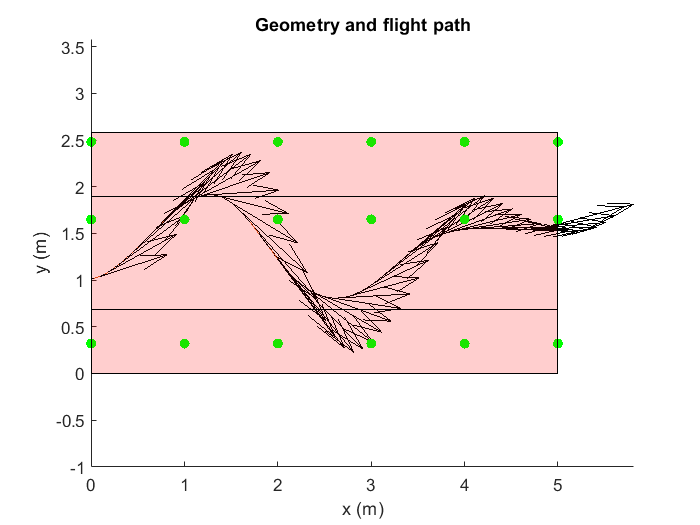

% %set the speed that the bat flies (m/s)
% batSpeed = 2;
% 
% %set the start location
% startLoc = [centerPoint(1),centerPoint(2),0];
% %set the timesteps
% tSteps = [0:0.1:5];
% 
% %set the minimum speed the bat moves in the z (to allow for the bat to
% %leave the array)
% batSpeedZ = 0.3;
% 
% %create an initial set of points to interpolate
% batPoints = startLoc;
% for i = 1:length(tSteps)
%     %set the movement vector
%     movementVec = rand([1,3]);
%     movementVec = movementVec/norm(movementVec);
%     movementVec = movementVec*batSpeed;
%     if movementVec(3) <= batSpeedZ
%         movementVec(3) = batSpeedZ;
%         movementVec = movementVec/norm(movementVec);
%         movementVec = movementVec*batSpeed;
%     end
%     
%     %get the next location
%     nextLoc = batPoints(i) + movementVec;
%     batPoints = [batPoints;nextLoc];
% end
% 
% %interpolate
% flightPoints = interparc(1000,batPoints(:,1),batPoints(:,2),batPoints(:,3));
% 
% %plot it
% plot3(flightPoints(:,1),flightPoints(:,2),flightPoints(:,3));
%better way to do this is to take the X and Y and find the maximums and minimums and then
%don't generate any x or y displacements which are too far outside that at
%each time step, and skew to x and y generating zeros (use a gaussian for
%this hehehe)

%algorithm
%set the center point to the center point (x,y) of the array
%set the current point to the start location at the center
%LOOP: continue until Z value is greater than the max Z value possible (out
%of the array)
%start with the current value 
%find distance between current value and center (dcurr)
%the dist between center point and edge of array (radius) minus dcurr is
%the max x and y value we can have
%sample x y and z from a gaussian with min and max we found earlier, for z, move the center
%from 0 and take abs of value we get to make sure bat only moves in the
%forward direction

%once we have all the points, find the total distance and compute how long
%it would take based on the speed

%finally interpolate based on number of timesteps needed

%much simpler way lol
tSpan = 0:1:50;
flightData = generateSimpleFlightPattern(arrayFullGeomData,tSpan,0.5,0.25,1);


figure(1)
clf
hold on
%for each timestep


%mic positions
scatter3(arrayFullGeomData.micPositions(:,3),arrayFullGeomData.micPositions(:,2),arrayFullGeomData.micPositions(:,1),'g','filled');

%plot the rectangles
for i = 1:7
    patch(arrayFullGeomData.rectangles(i,:,3),arrayFullGeomData.rectangles(i,:,2),arrayFullGeomData.rectangles(i,:,1),[1 0 0],"FaceAlpha",0.1);
end

patch(arrayFullGeomData.rectangles(8,:,3),arrayFullGeomData.rectangles(8,:,2),arrayFullGeomData.rectangles(8,:,1),[1 0 0],"FaceAlpha",0.1);    
plot3(flightData.Locations(:,3),flightData.Locations(:,2),flightData.Locations(:,1));

%plot the bat directions
quiver3(flightData.Locations(:,3),flightData.Locations(:,2),flightData.Locations(:,1),flightData.Directions(:,3),flightData.Directions(:,2),flightData.Directions(:,1),2,"filled",'k');
title("Geometry and flight path")
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')
axis equal

hold off